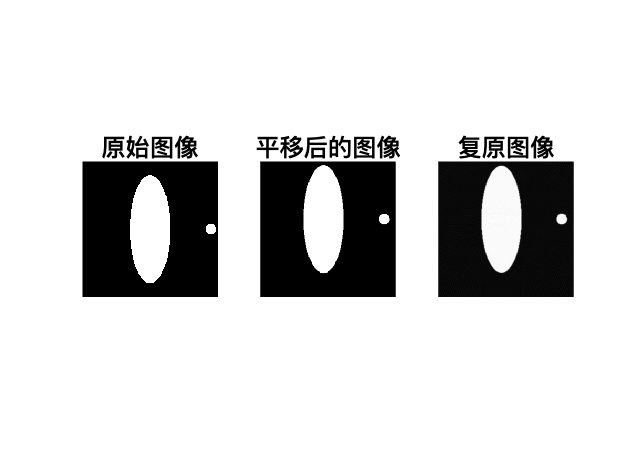

F5 = iradon(File5, theta, 'linear', 'Ram-Lak', 1, 512);
I = imresize(F5,0.5);

% 使用估计的旋转中心和初始角度进行逆 Radon 变换
% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I) / 2;
tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I_translated = imwarp(I, tform, 'OutputView', imref2d(size(I)));

% 旋转图像，使得初始角度为 0
I_rotated = imrotate(I_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 计算 Radon 变换
R_estimated = radon(I_rotated, theta);

% 使用逆 Radon 变换复原图像
I_reconstructed = iradon(R_estimated, theta);

% 绘制原始图像和复原图像
figure;
subplot(1,2,1);
imshow(I, []);
title('原始附件2图像');

subplot(1,2,2);
imshow(I_reconstructed, []);
title('附件二复原后图像');